load data.txt
load matlab.mat

%1,G
% Normalizing the age of properties based on z􀀀score normalization.
normAge=normalize(Age)

normAge =     1.1754
    1.1754
   -0.7420
   -0.8895
   -0.5945
   -1.0370
   -0.8895
   -0.7420
    1.0279
    1.7654


z=zscore(Age)

z =     1.1754
    1.1754
   -0.7420
   -0.8895
   -0.5945
   -1.0370
   -0.8895
   -0.7420
    1.0279
    1.7654


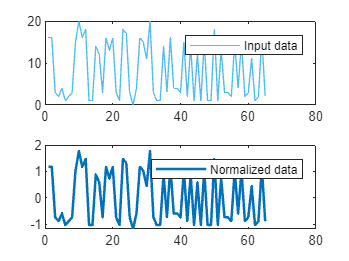

% Normalize Data
[normalizedData2,centerValue2,scaleValue2] = normalize(Age);

% Display results
clf
tiledlayout(2,1);
nexttile
plot(Age,"Color",[77 190 238]/255,"DisplayName","Input data")
legend

nexttile
plot(normalizedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Normalized data")
legend

figure

%1.H
% Normalizing the age of properties by z-score normalization using mean absolute deviation
% instead of standard deviation.

% finding mean absolute deviation
%Mad=mad(Age)
% finding mean
%meanAge=mean(Age)

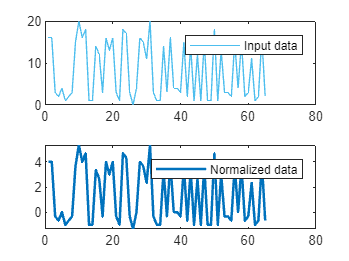

% Normalize Data
[normalizedData,centerValue,scaleValue] = normalize(Age,"zscore","robust");

% Display results
clf
tiledlayout(2,1);
nexttile
plot(Age,"Color",[77 190 238]/255,"DisplayName","Input data")
legend

nexttile
plot(normalizedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Normalized data")
legend

figure

normAbsDev=normalize(Age,"zscore","robust")

normAbsDev =     4.0000
    4.0000
   -0.3333
   -0.6667
         0
   -1.0000
   -0.6667
   -0.3333
    3.6667
    5.3333


% 1.I

% The normalized values represent the number of standard deviations the original value is from 
% the mean.
%The MAD is generally preferred over using the standard deviation of the data when the data contains
% outliers because the standard deviation squares deviations from 
% the mean, giving outliers an unduly large impact. Conversely, the deviations of a small number of 
% outliers do not affect the value of the MAD.

% 2.
%2.6 Given two objects represented by the tuples (22, 1, 42, 10) and (20, 0, 36, 8):
X=[22,1,42,10]

X =     22     1    42    10


Y=[20,0,36,8]

Y =     20     0    36     8


%(a) Compute the Euclidean distance between the two objects.
deuc=pdist2(X,Y)

deuc = 6.7082

%(b) Compute the Manhattan distance between the two objects.
dman=pdist2(X,Y,'cityblock')

dman = 11

%(c) Compute the Minkowski distance between the two objects, using q D 3.
dmin=pdist2(X,Y,'minkowski',3)

dmin = 6.1534

%(d) Compute the supremum distance between the two objects.
dsup=pdist2(X,Y,'minkowski',inf)

dsup = 6